n = 6;
A = rand(n);
X_ex = ones(n,1);
b = A*X_ex;

b2 = b.*(rand(n, 1) * 0.1 - 0.05 + 1);
x = A\b2;

err_x = norm(x-X_ex)/norm(x)

err_x =    0.173783830967757


err_b = norm(b - b2)/norm(b)

err_b =    0.030296804050644


c = cond(A)

c =   34.688326588213975


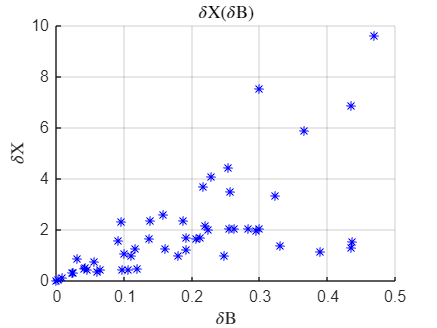


figure
hold on
grid on

gen1(n, A, X_ex, b);

title("$\delta$X($\delta$B)", 'Interpreter', 'latex')
xlabel("$\delta$B", 'Interpreter', 'latex')
ylabel("$\delta$X", 'Interpreter', 'latex')


figure
hold on
grid on

gen2(n, 0.1, X_ex);

db =    1.025661607646378
   0.991659443850651
   1.045667202150135
   1.015275928963713
   0.983828691348907
   1.020004712206526


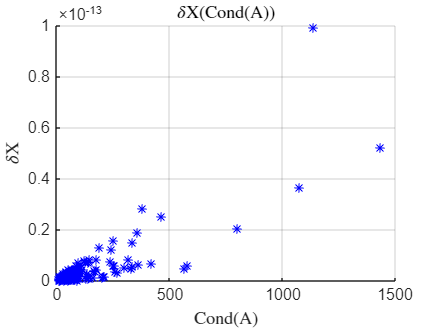


title("$\delta$X(Cond(A))", 'Interpreter', 'latex')
xlabel("Cond(A)", 'Interpreter', 'latex')
ylabel("$\delta$X", 'Interpreter', 'latex')

xlim([0, 1500])


function [x, y] = gen2(n, perr, x_ex)
    x_bon = zeros(n, 1);
    y_bon = zeros(n, 1);
    k = 1;
    
    db = rand(n, 1) * perr - perr/2 + 1

    for i = 1:300
        A = rand(n);
        b_ex = A*x_ex;
        b = b_ex;
        x = A\b;

        err_x = norm(x-x_ex)/norm(x_ex);
        cond_a = cond(A);
        
        x_bon(k) = cond_a;
        y_bon(k) = err_x;

        plot(cond_a, err_x, '*b');
        k = k + 1;
    end
    
    p = boundary(y_bon, x_bon, 1);
    %plot(x_bon(p), y_bon(p), 'r--')
    %patch(x_bon(p), y_bon(p), [1 1 1], 'FaceAlpha',0.25)
end


function [x, y] = gen1(n, A, x_ex, b_ex)
    x_bon = zeros(n, 1);
    y_bon = zeros(n, 1);
    k = 1;

    for i = 0:0.01:0.5
        b = b_ex.*(rand(n, 1) * 2 * i - i/2 + 1);
        x = A\b;

        err_x = norm(x-x_ex)/norm(x_ex);
        err_b = norm(b-b_ex)/norm(b_ex);
        
        x_bon(k) = err_b;
        y_bon(k) = err_x;

        plot(err_b, err_x, '*b');
        k = k + 1;
    end
    
    p = boundary(y_bon, x_bon, 1);
    %plot(x_bon(p), y_bon(p), 'r--')
    %patch(x_bon(p), y_bon(p), [1 1 1], 'FaceAlpha',0.25)
end